# Thermal Calculator

Main Document [here](https://docs.google.com/document/d/1MgEfN8uAGja6VMx7kqAkoUOlrUCEuHOKKBFwb_MEE9E/edit?usp=sharing)

Thermal Stage Doc [here](https://docs.google.com/document/d/1LFotCKugJQmg7X97VCYzZdj7jm384hpMmckm8d77kWU/edit)

## Physical Constants

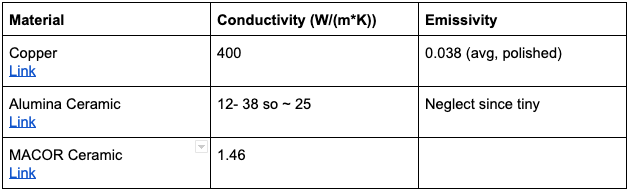

For zirconia spacers (k = 2.2 W/(m*K)) for M3 screws from [here](https://www.ortechceramics.com/products/uncategorized/ceramic-washers/)

- Inner diameter 3.50 – 3.68

- Outer diameter 9.64 – 10.0

- Thickness 0.80 – 1.20

Glass spacers from pyrex might be better

load ImpVariables.mat;
mat2Cond = 1; % for glass
mat1Emis = 0.038; % for polished copper

## Radiation Term


$$P_{rad} = e\sigma A(T_{hot}^4 - T_{room}^4)$$


% Object Dimensions
length = 20*mil;
width = 7*mil;
thick = 3*mil;
surfaceArea = 2*length*width+ 2*length*thick + 2*thick*width;
zeroC = 273.15;
T_hot = 250 + zeroC;
T_cold = 20 + zeroC;
P_rad = mat1Emis*SI_stfn_boltz*surfaceArea*(T_hot^4-T_cold^4)

P_rad = 0.0643

## Conduction Term

Assuming cylindrical spacers of height and internal/external radiuses given, with perfect thermal contact

height = 10*mil;
inRad = 3.5*mil;
outRad = 4.5*mil;

condArea = pi*outRad^2 - pi*inRad^2;
P_cond = mat2Cond*condArea*(T_hot-T_cold)/height

P_cond = 0.5781